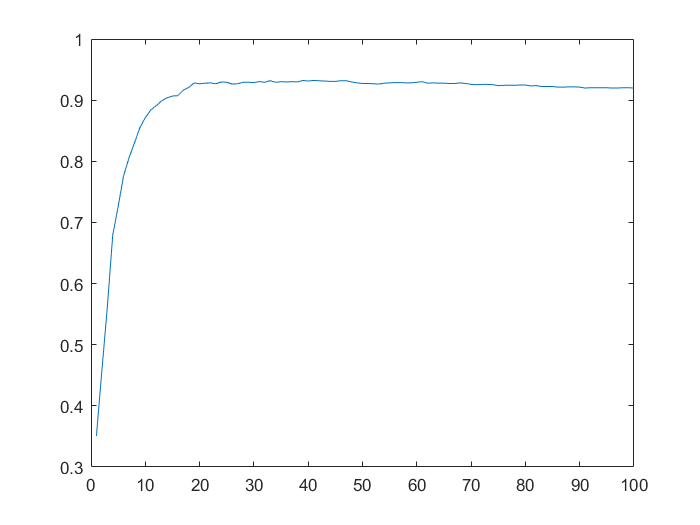

% znamenke

clear
clc

load azip   % 16 x 16 bitmape vekorizirane u 256 x 1 stupce od A
load dzip   % dzip(i) = j <=> i-stupac od A sadrzi znamenku j

A = azip ; % A(:,i) je 256 x 1 = vektorizirana slika znamenke rez. 16 x 16
D = dzip ; % D(i) je 0, ..., 9; oznacava koja znamenka je u A(:,i)
% podaci za testiranje
load testzip % 16 x 16 bitmape vekorizirane u 256 x 1 stupce od A1
load dtest   % dzip(i) = j <=> i-stupac od A1 sadrzi znamenku j
A1 = testzip ;
D1 = dtest   ;

%PCA
graf = zeros(100,1);
%parfor k = 1:100
%graf(k) = MatrixPCA(A, A1, k, D, D1); % spremi graf jer je spor ko blato
%end
load('PCA_znam_graph.mat')
plot(graf);


% tSVD1
[mA,nA] = size(A) ;
for i = 1 : nA
    TA(:,i,:) = reshape( A(:,i), 16, 16 ) ;
end

Undefined function or variable 'nA'.

[mA1,nA1] = size(A1) ;
for i = 1 : nA1
    TA1(:,i,:) = reshape( A1(:,i), 16, 16 ) ;
end

ks = [4 6 13 7 4 7 6 2 4 6];
%FaceRecognition_tSVD1(TA, TA1, ks, D, D1);

%tSVD2

%QR
graf = zeros(32, 1);
U = tQR(TA);
% parfor k = 1:32
%     % za tSVD_ver2 novi U za svaki k
%     graf(k) = FaceRecognition_tSVD1_ver2(TA, TA1, k, D, D1, U);
% end
load('QR_znam_graph.mat')
plot(graf);


% face
clear
clc

load('YaleB_32x32.mat');

[nSmp,nFea] = size(fea);
% normalizacija
parfor i = 1:nSmp
    fea(i,:) = fea(i,:) ./ max(1e-12,norm(fea(i,:)));
end
str = ['20Train/17.mat'];
load(str);
fea_Train = fea(trainIdx,:);
fea_Test = fea(testIdx,:);

gnd_Train = gnd(trainIdx);
gnd_Test = gnd(testIdx);

graf = zeros(100,1);
parfor k = 1:200
    graf(k) = MatrixPCA( fea_Train', fea_Test', k, gnd_Train, gnd_Test );
end
plot(graf);


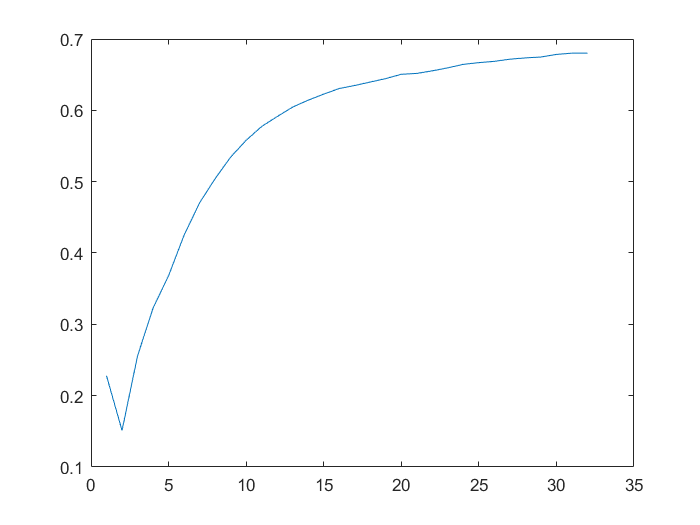


% tSVD1
cnt1 = 1;
cnt2 = 1;
for i = 1 : size(fea,1)
    if ismember(i,trainIdx)
        TA(:,cnt1,:) = reshape(fea_Train(cnt1,:),[32,32]) ;
        cnt1 = cnt1 + 1;
    else
        TJ(:,cnt2,:) = reshape(fea_Test(cnt2,:),[32,32]) ;
        cnt2 = cnt2 + 1;
    end
end
graf = zeros(32,1);
parfor k = 1:32
    U = T_SVD(TA,k);
    percentage = FaceRecognition_tSVD1_ver2( TA, TJ, k, gnd_Train, gnd_Test, U );
    graf(k) = percentage;
end
plot(graf)


%tSVD2


%QR
graf = zeros(100,1);
U = tQR(TA);
parfor k = 1:100
    k
    percentage = FaceRecognition_tSVD1_ver2( TA, TJ, k, gnd_Train, gnd_Test, U );
    graf(k) = percentage;
end


ans =

     1


ans =

     2


ans =

     4


ans =

     7


ans =

    12


ans =

    20


ans =

    29


ans =

    38


ans =

     3


ans =

     6


ans =

    11


ans =

    19


ans =

    47


ans =

     5


ans =

    28


ans =

    10


ans =

    37


ans =

    18


ans =

    56


ans =

     9


ans =

    27


ans =

    46


ans =

    17


ans =

    36


ans =

     8


ans =

    55


ans =

    16


ans =

    26


ans =

    45


ans =

    64


ans =

    35


ans =

    15


ans =

    25


ans =

    54


ans =

    34


ans =

    44


ans =

    14


ans =

    63


ans =

    24


ans =

    13


ans =

    33


ans =

    53


ans =

    43


ans =

    23


ans =

    70


ans =

    62


ans =

    32


ans =

    22


ans =

    42


ans =

    52


ans =

    21


ans =

    31


ans =

    61


ans =

    69


ans =

    41


ans =

    51


ans =

    75


ans =

    30


ans =

    60


ans =

    40


ans =

    50


ans =

    68


ans =



plot(graf)
